# Degradation Curves

Use this file to

- view the curves

- accelerate them

- alter them

- save them

load Q_degradation.csv
load R0_degradation.csv
% motor deg is derived below

## Plot the curves

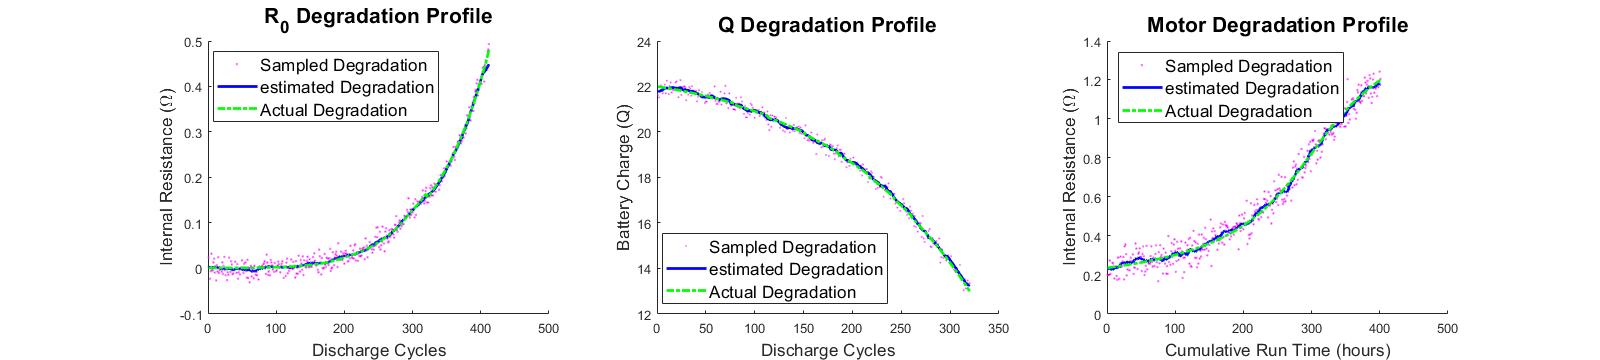

rdeg = interp1([R0_degradation(1) R0_degradation(end)], [.0011 0.48], R0_degradation);
rdegr = normrnd(rdeg, .013);
restr = movmean(rdegr, 22);

frdeg = figure("Name", "rdeg"); clf;
frdeg.Position = [0 0 1600 360];
subplot(1,3,1);
hold on;
plot(rdegr, 'm.', 'markersize', 3, "DisplayName", "Sampled Degradation");
plot(restr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(rdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Internal Resistance (\Omega)",  'fontsize', 13);
title("R_0 Degradation Profile", 'fontsize', 16);
legend('location', 'best',  'fontsize', 13);


qdeg = interp1([Q_degradation(1) Q_degradation(end)], [22 13], Q_degradation);
qdegr = normrnd(qdeg, .2);
qestr = movmean(qdegr, 10);
subplot(1,3,2);
% fqdeg = figure("Name", "qdeg"); clf;
% fqdeg.Position = [0 0 800 400];
hold on;
plot(qdegr, 'm.', 'markersize', 1, "DisplayName", "Sampled Degradation");
plot(qestr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(qdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Battery Charge (Q)",  'fontsize', 13);
title("Q Degradation Profile", 'fontsize', 16);
legend('Location', 'best',  'fontsize', 13);
x = -15:.05:05;
y = atan(x/5)/7;
mdeg = interp1([y(1) y(end)], [.2371 1.2], y);
mdegr = normrnd(mdeg, .05);
mestr = movmean(mdegr, 15);
% fmdeg = figure("Name", "mdeg"); clf;
% fmdeg.Position = [0 0 800 400];
subplot(1,3,3);
hold on;
plot(mdegr, 'm.', 'markersize', 3, "DisplayName", "Sampled Degradation");
plot(mestr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(mdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Cumulative Run Time (hours)", 'fontsize', 13);
ylabel("Internal Resistance (\Omega)", 'fontsize', 13);
title("Motor Degradation Profile", 'fontsize', 16);
legend('location', 'northwest', 'fontsize', 13);

## Convert from cycles to runtime

p = polyfit([412:-1:1], rdeg, 3)

p =    -0.0000    0.0000   -0.0044    0.4568


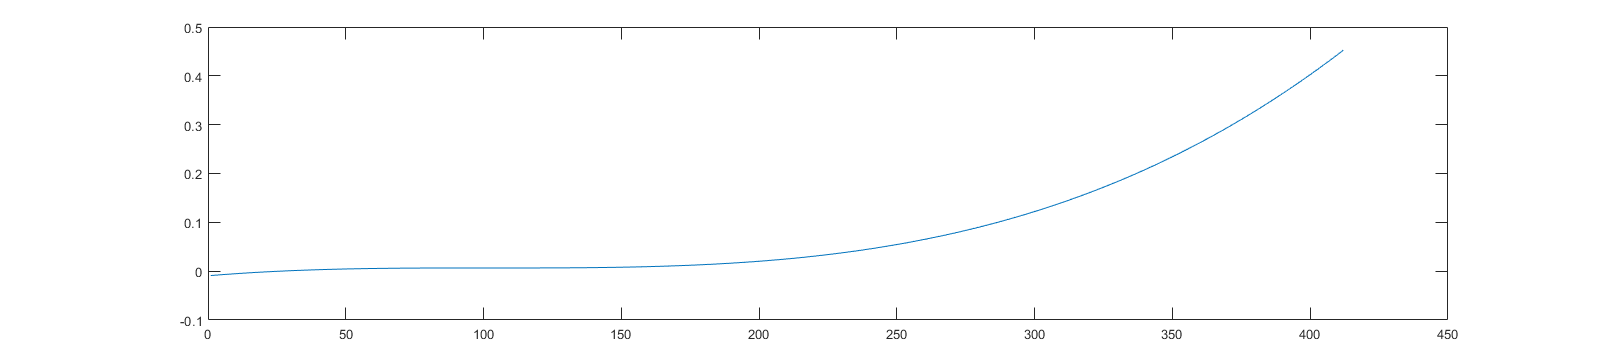

res = polyval(p, [412:-1:1]);
f2 = figure(2); clf;
f2.Position = [0 0 600 600];
set(gcf, 'Resize', 'off')
plot(res)

f3 = figure(3); clf;
f3.Position = [0 0 600 600]
plot([1:1:20])


## Save the curves

save('params\rdeg.mat', 'rdeg');
save('params\qdeg.mat', 'qdeg');
save('params\mdeg.mat', 'mdeg');

## Downsample the curve (artificial acceleration)

rdown = downsample(rdeg, 2);
qdown = downsample(qdeg, 2);
%mdown = downsample(mdeg, 2)';
%rdown = rdeg;
mdown = mdeg';

f2 = figure(2); clf;
f2.Position = [0 0 1200 300];
subplot(1,3,1);
plot(rdown);
xlabel("Discharge Cycles (Accelerated)",  'fontsize', 13);
ylabel("Internal Resistance (\Omega)",  'fontsize', 13);
title("R_0 Degradation Profile", 'fontsize', 16);
legend('location', 'best',  'fontsize', 13);
subplot(1,3,2);
plot(qdown);
xlabel("Discharge Cycles (Accelerated)",  'fontsize', 13);
ylabel("Battery Charge (Q)",  'fontsize', 13);
title("Q Degradation Profile", 'fontsize', 16);
legend('Location', 'best',  'fontsize', 13);
subplot(1,3,3);
plot(mdown);
xlabel("Cumulative Run Time (hours - Accelerated)", 'fontsize', 13);
ylabel("Internal Resistance (\Omega)", 'fontsize', 13);
title("Motor Degradation Profile", 'fontsize', 16);
legend('location', 'southeast', 'fontsize', 13);

## Save the accelerated curves

save('degradation\rdeg.mat', 'rdeg');
save('degradation\qdeg.mat', 'qdeg');
save('degradation\mdeg.mat', 'mdeg');

save('degradation\rdown.mat', 'rdown');
save('degradation\qdown.mat', 'qdown');
save('degradation\mdown.mat', 'mdown');

f3 = figure("name", "deg"); clf;
f3.Position = [0 0 1200 400];
subplot(1,3,1);
plot(rdeg);
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Internal Resistance (\Omega)",  'fontsize', 13);
title("R_0 Degradation Profile", 'fontsize', 16);
legend('location', 'best',  'fontsize', 13);

subplot(1,3,2);
plot(qdeg);
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Battery Charge (Q)",  'fontsize', 13);
title("Q Degradation Profile", 'fontsize', 16);
legend('Location', 'best',  'fontsize', 13);

subplot(1,3,3);
plot(mdeg);
xlabel("Cumulative Run Time (hours)", 'fontsize', 13);
ylabel("Internal Resistance (\Omega)", 'fontsize', 13);
title("Motor Degradation Profile", 'fontsize', 16);
legend('location', 'southeast', 'fontsize', 13);
sgtitle('degradation parameters');

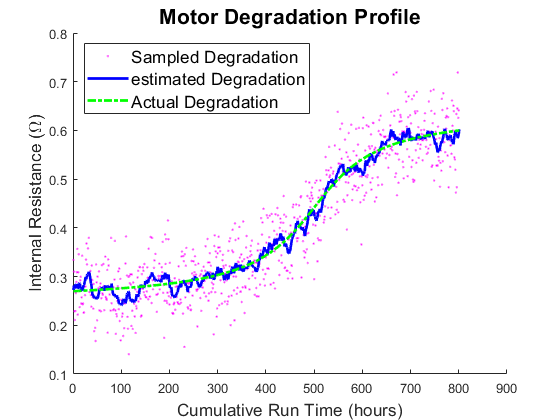

f1 = figure(1); clf;
f1.Position = [0 0 900 400];
x = -25:.05:15;
coef = [1/20 1/5];
y = coef(1)*atan(coef(2)*x);
mdeg = interp1([y(1) y(end)], [.27 .6], y);
mdegr = normrnd(mdeg, .05);
mestr = movmean(mdegr, 15);
% fmdeg = figure("Name", "mdeg"); clf;
% fmdeg.Position = [0 0 800 400];
hold on;
plot(mdegr, 'm.', 'markersize', 3, "DisplayName", "Sampled Degradation");
plot(mestr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(mdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Cumulative Run Time (hours)", 'fontsize', 13);
ylabel("Internal Resistance (\Omega)", 'fontsize', 13);
title("Motor Degradation Profile", 'fontsize', 16);
legend('location', 'northwest', 'fontsize', 13);

length(x)

ans = 801

24*length(x)

ans = 19224

motor_max_amp_hrs = 20*length(x)/8

motor_max_amp_hrs = 2.0025e+03

length(mdeg)

ans = 801

x2 = [0:2.5:motor_max_amp_hrs-1];

length(x2)

ans = 801

p = polyfit(x2, mdeg, 8);

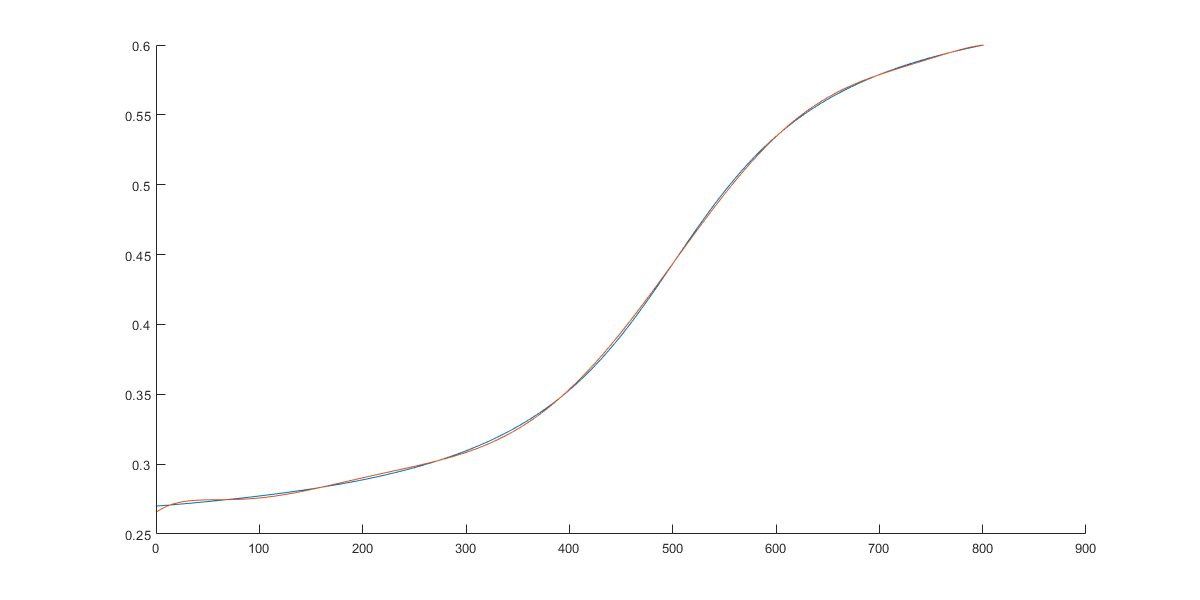

y2 = polyval(p, x2);
f2 = figure(2); clf;
f2.Position = [0 0 1200 600];
hold on;
plot(mdeg);
plot(y2(1:end));
hold off;

p

p =    -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0002    0.2660


Unable to resolve the name uav.motors.

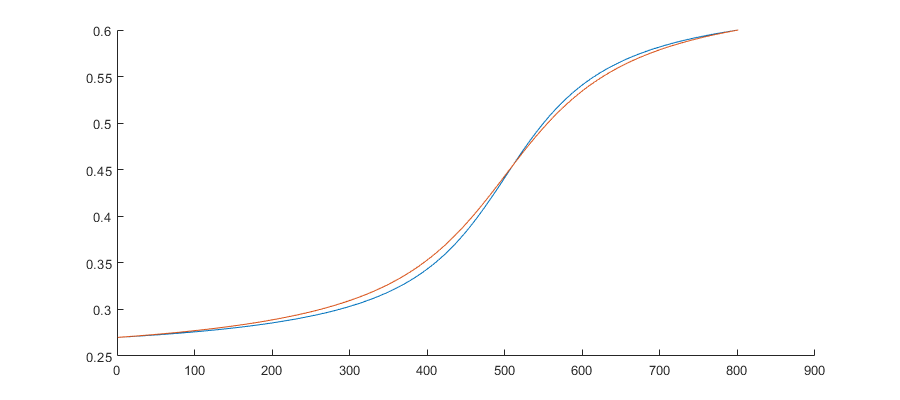

f1 = figure(1); clf;
f1.Position = [0 0 900 400];
x = -25:.05:15;
coef = [1/20 1/5];
y = coef(1)*atan(coef(2)*x);
mdeg = interp1([y(1) y(end)], [.27 .6], y);
hold on;
plot(mdeg);
coef = [1/7 1/6];
y = coef(1)*atan(coef(2)*x);
mdeg = interp1([y(1) y(end)], [.27 .6], y);
plot(mdeg);
hold off;

x2

x2 = 	1.0e+03 *

         0    0.0025    0.0050    0.0075    0.0100    0.0125    0.0150    0.0175    0.0200    0.0225    0.0250    0.0275    0.0300    0.0325    0.0350    0.0375    0.0400    0.0425    0.0450    0.0475    0.0500    0.0525    0.0550    0.0575    0.0600    0.0625    0.0650    0.0675    0.0700    0.0725    0.0750    0.0775    0.0800    0.0825    0.0850    0.0875    0.0900    0.0925    0.0950    0.0975    0.1000    0.1025    0.1050    0.1075    0.1100    0.1125    0.1150    0.1175    0.1200    0.1225


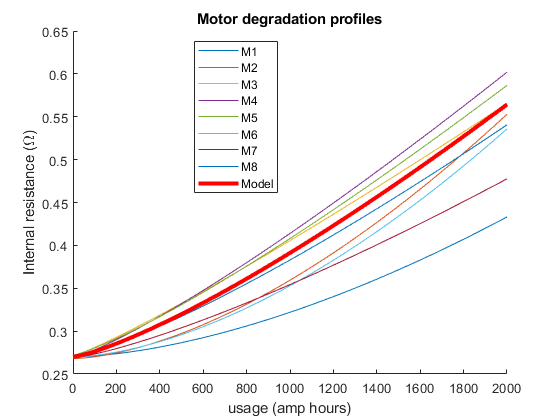

f3 = figure(3); clf;
hold on;
y1 = (x2/6000).^1.65 + .27;
y2 = (x2/4300).^1.64 + .268;
y3 = (x2/5900).^1.13 + .271;
y4 = (x2/5000).^1.2 + .269;
y5 = (x2/5200).^1.21 + .272;
y6 = (x2/4400).^1.68 + .27;
y7 = (x2/6740).^1.29 + .269;
y8 = (x2/5643).^1.26 + .27;
ym = (x2/5200).^1.28 + .27;

plot(x2, y1, 'DisplayName', 'M1');
plot(x2, y2, 'DisplayName', 'M2');
plot(x2, y3, 'DisplayName', 'M3');
plot(x2, y4, 'DisplayName', 'M4');
plot(x2, y5, 'DisplayName', 'M5');
plot(x2, y6, 'DisplayName', 'M6');
plot(x2, y7, 'DisplayName', 'M7');
plot(x2, y8, 'DisplayName', 'M8');
plot(x2, ym, 'r-', 'LineWidth', 3, 'DisplayName', 'Model');
legend('location', 'best');
title("Motor degradation profiles");
xlabel("usage (amp hours)");
ylabel("Internal resistance (\Omega)")
hold off;

deg = 2;
p1 = polyfit(x2, y1, deg);
yp1 = polyval(p1, x2);

p2 = polyfit(x2, y2, deg);
yp2 = polyval(p2, x2);

p3 = polyfit(x2, y3, deg);
yp3 = polyval(p3, x2);

p4 = polyfit(x2, y4, deg);
yp4 = polyval(p4, x2);

p5 = polyfit(x2, y5, deg);
yp5 = polyval(p5, x2);

p6 = polyfit(x2, y6, deg);
yp6 = polyval(p6, x2);

p7 = polyfit(x2, y7, deg);
yp7 = polyval(p7, x2);

p8 = polyfit(x2, y8, deg);
yp8 = polyval(p8, x2);

pm = polyfit(x2, ym, deg);
ypm = polyval(pm, x2);


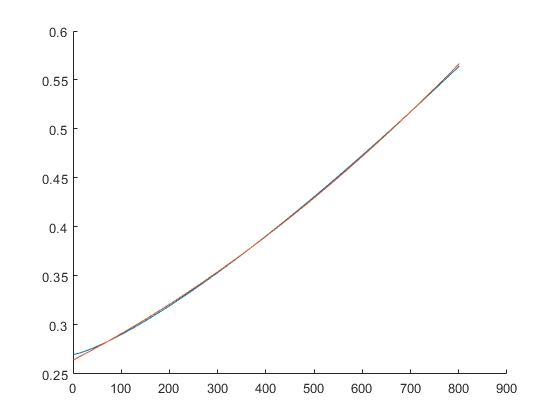

f6 = figure(6); clf;
hold on;
plot(ym);
plot(ypm);
hold off;

p1

p1 =     0.0000    0.0000    0.2675


p2

p2 =     0.0000    0.0000    0.2636


p3

p3 =     0.0000    0.0001    0.2674


p4

p4 =     0.0000    0.0001    0.2636


p5

p5 =     0.0000    0.0001    0.2668


p6

p6 =     0.0000    0.0000    0.2663


p7

p7 =     0.0000    0.0001    0.2650


p8

p8 =     0.0000    0.0001    0.2650


uav.motors(1).r_coef = p1;
uav.motors(2).r_coef = p2;
uav.motors(3).r_coef = p3;
uav.motors(4).r_coef = p4;
uav.motors(5).r_coef = p5;
uav.motors(6).r_coef = p6;
uav.motors(7).r_coef = p7;
uav.motors(8).r_coef = p8;

save('estimation/mestcoef.mat', 'pm')


x = [0:22:7018]

x =            0          22          44          66          88         110         132         154         176         198         220         242         264         286         308         330         352         374         396         418         440         462         484         506         528         550         572         594         616         638         660         682         704         726         748         770         792         814         836         858         880         902         924         946         968         990        1012        1034        1056        1078


length(x)

ans = 320

qdeg = interp1([Q_degradation(1) Q_degradation(end)], [22 4], Q_degradation)

qdeg =    22.0000
   21.9858
   21.9717
   21.9547
   21.9420
   21.9278
   21.9122
   21.8967
   21.8825
   21.8669


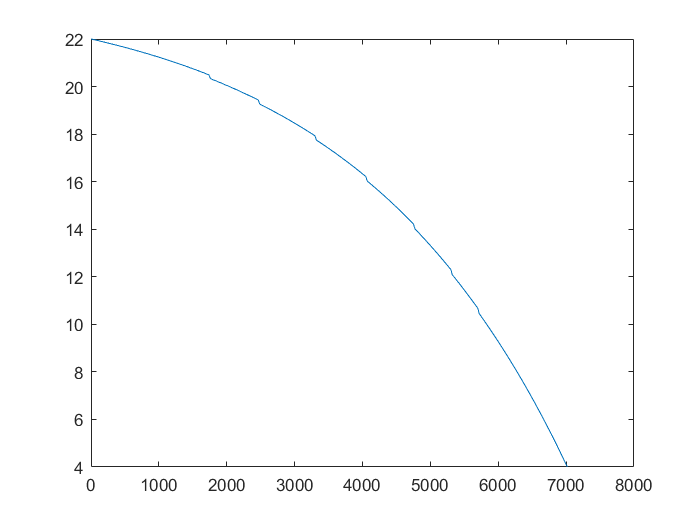

plot(x, qdeg)

p = polyfit(x, qdeg, 2);

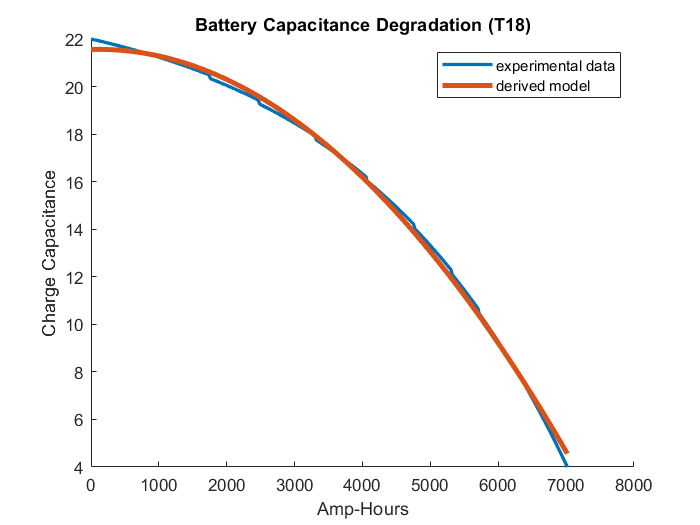

f1 = figure(1); clf;
y = polyval(p, x);
hold on;
plot(x,qdeg, 'DisplayName', 'experimental data', 'LineWidth', 2);
plot(x,y, 'DisplayName', 'derived model', 'LineWidth', 3);
title("Battery Capacitance Degradation (T18)");
xlabel("Amp-Hours");
ylabel("Charge Capacitance")
hold off;
legend;

rdeg = interp1([R0_degradation(1) R0_degradation(end)], [.0011 0.11], R0_degradation)

rdeg =     0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011


x = [1:17:7004]

x =      1    18    35    52    69    86   103   120   137   154   171   188   205   222   239   256   273   290   307   324   341   358   375   392   409   426   443   460   477   494   511   528   545   562   579   596   613   630   647   664   681   698   715   732   749   766   783   800   817   834


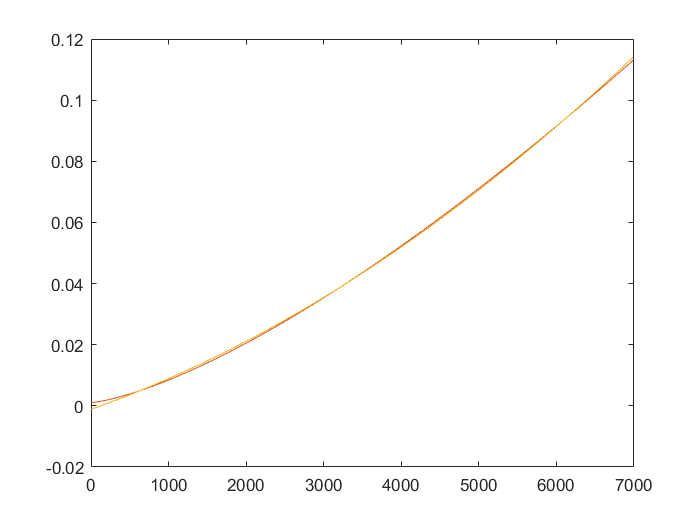

r = (x/33400).^1.4 + .0011;
plot(x,r)
p = polyfit(x, r, 2);
yr = polyval(p, x);
hold on;
plot(x, r);
plot(x, yr);
hold off;

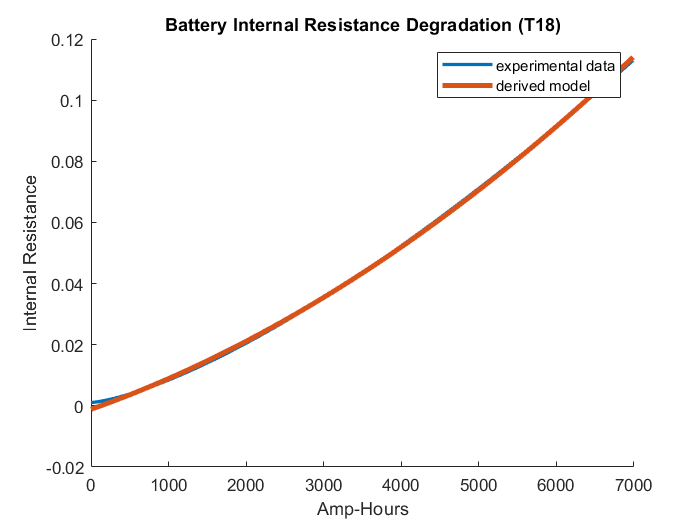

clf;
y = polyval(p, x);
%plot(x,y, "DisplayName", 'poly');
hold on;
%plot(x,r);
plot(x,r, 'DisplayName', 'experimental data', 'LineWidth', 2);
plot(x,y, 'DisplayName', 'derived model', 'LineWidth', 3);
title("Battery Internal Resistance Degradation (T18)");
xlabel("Amp-Hours");
ylabel("Internal Resistance")
legend;
hold off;

polyval(p, 2000)

ans = 0.0211

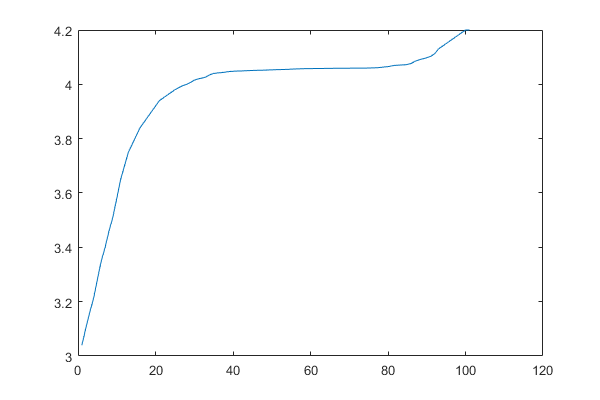

f5 = figure(5); clf;
x = [1:1:length(soc_ocv)];
plot(x, soc_ocv);

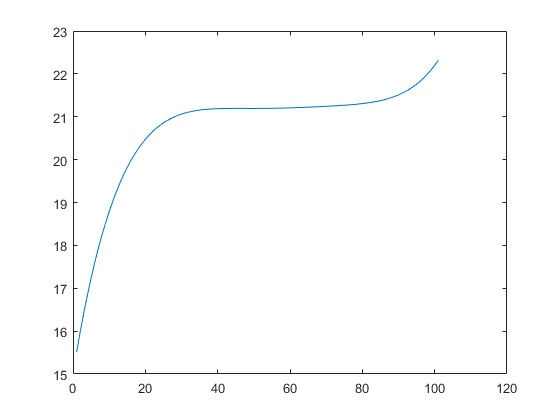

f6 = figure(6); clf;
y = polyval(z_coef, x);
plot(x,y);